addpath('G:\My Drive\Matlab_work\BC\Sea-Bird_Oxygen_Toolbox')
addpath('G:\My Drive\Matlab_work\BC\Sea-Bird-Toolbox')
addpath('G:\My Drive\Matlab_work\Functions\GSW')

cd('G:\Shared drives\NSF_Irminger\OOI Cruises CTD Casts\CTD_Data\Alfresco\Year2')


% Configuration file was changed on xlmcon and then files were processed
% using Leah's processing pipeline 

cast01 = readSBScnv( 'uat30_001_KFabcdef.cnv' );
cast02 = readSBScnv( 'uat30_002_KFabcdef.cnv' );
cast03 = readSBScnv( 'uat30_003_KFabcdef.cnv' ); 
cast04 = readSBScnv( 'uat30_004_KFabcdef.cnv' );
cast05 = readSBScnv( 'uat30_005_KFabcdef.cnv' );
cast06 = readSBScnv( 'uat30_006_KFabcdef.cnv' );
cast07 = readSBScnv( 'uat30_007_KFabcdef.cnv' );
cast08 = readSBScnv( 'uat30_008_KFabcdef.cnv' );
cast09 = readSBScnv( 'uat30_009_KFabcdef.cnv' );
cast10 = readSBScnv( 'uat30_010_KFabcdef.cnv' );
cast11 = readSBScnv( 'uat30_011_KFabcdef.cnv' );
cast12 = readSBScnv( 'uat30_012_KFabcdef.cnv' );
cast13 = readSBScnv( 'uat30_013_KFabcdef.cnv' );


cd('G:\Shared drives\NSF_Irminger\OOI Cruises CTD Casts\CTD_Data\Alfresco\Year2')
btl = readtable('Irminger_Sea-02_AT30-01_Discrete_Summary_KF.xlsx','TextType','string');
btl.Winkler_mLL = double(btl.Winkler_mLL);
btl.Discrete_Salinity_psu = double(btl.Discrete_Salinity_psu);

btlsum03 = btl(btl.Cast == 3,:);
btlsum04 = btl(btl.Cast == 4,:);
btlsum05 = btl(btl.Cast == 5,:);
btlsum06 = btl(btl.Cast == 6,:);
btlsum09 = btl(btl.Cast == 9,:);
btlsum10 = btl(btl.Cast == 10,:);
btlsum11 = btl(btl.Cast == 11,:);
btlsum12 = btl(btl.Cast == 12,:);
btlsum13 = btl(btl.Cast == 13,:);

cd('G:\Shared drives\NSF_Irminger\OOI Cruises CTD Casts\CTD_Data\Alfresco\Year2\Outputs')
btl03 = readtable('at30_003_KF_hyst.csv','TextType','string');

btl04 = readtable('at30_004_KF_hyst.csv','TextType','string');

btl05 = readtable('at30_005_KF_hyst.csv','TextType','string');

btl06 = readtable('at30_006_KF_hyst.csv','TextType','string');

btl09 = readtable('at30_009_KF_hyst.csv','TextType','string');

btl10 = readtable('at30_010_KF_hyst.csv','TextType','string');

btl11 = readtable('at30_011_KF_hyst.csv','TextType','string');

btl12 = readtable('at30_012_KF_hyst.csv','TextType','string');

btl13 = readtable('at30_013_KF_hyst.csv','TextType','string');


% Join tables 
btlsum03 = join(btl03,btlsum03,'Keys',"Bottle");
btlsum04 = join(btl04,btlsum04,'Keys',"Bottle");
btlsum05 = join(btl05,btlsum05,'Keys',"Bottle");
btlsum06 = join(btl06,btlsum06,'Keys',"Bottle");
btlsum09 = join(btl09,btlsum09,'Keys',"Bottle");
btlsum10 = join(btl10,btlsum10,'Keys',"Bottle");
btlsum11 = join(btl11,btlsum11,'Keys',"Bottle");
btlsum12 = join(btl12,btlsum12,'Keys',"Bottle");
btlsum13 = join(btl13,btlsum13,'Keys',"Bottle");


clear btl0* btl1* btl2*
clear btl 

btlsum_yr2 = [btlsum03; btlsum04; btlsum05; btlsum06; btlsum09;...
    btlsum10; btlsum11; btlsum12; btlsum13];

cd('G:\Shared drives\NSF_Irminger\OOI Cruises CTD Casts\CTD_Data\Alfresco\Year2')
save Year2_Processed_KF cast* btl*

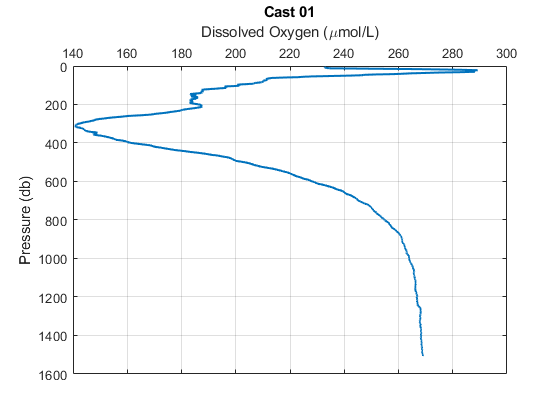

figure
plot(cast01.sbeox0mL_L*44.661,cast01.pm,'Linewidth',1.5)
axis ij
ax = gca;
ax.XAxisLocation = 'top';
xlabel('Dissolved Oxygen (\mumol/L)'); ylabel('Pressure (db)')
grid on
title('Cast 01')

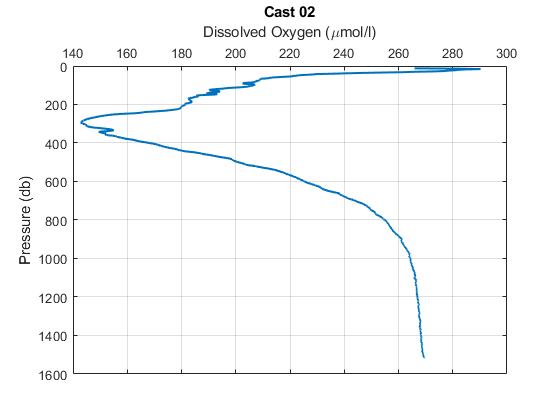


figure
plot(cast02.sbeox0mL_L*44.661,cast02.pm,'Linewidth',1.5)
axis ij
ax = gca;
ax.XAxisLocation = 'top';
xlabel('Dissolved Oxygen (\mumol/l)'); ylabel('Pressure (db)')
grid on
title('Cast 02')

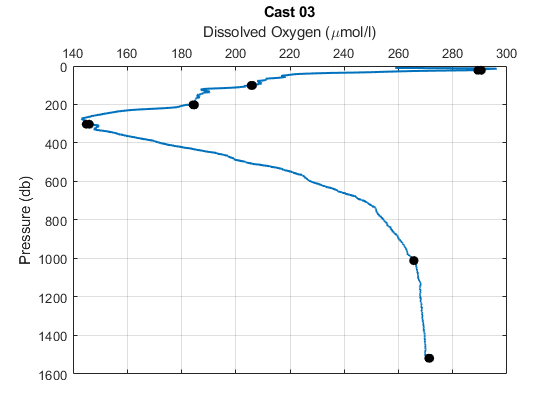


figure
plot(cast03.sbeox0mL_L*44.661,cast03.pm,'Linewidth',1.5)
hold on
plot(btlsum03.Winkler_mLL*44.661,btlsum03.PrDM,'ok','MarkerFaceColor','k')
axis ij
ax = gca;
ax.XAxisLocation = 'top';
xlabel('Dissolved Oxygen (\mumol/l)'); ylabel('Pressure (db)')
grid on
title('Cast 03')

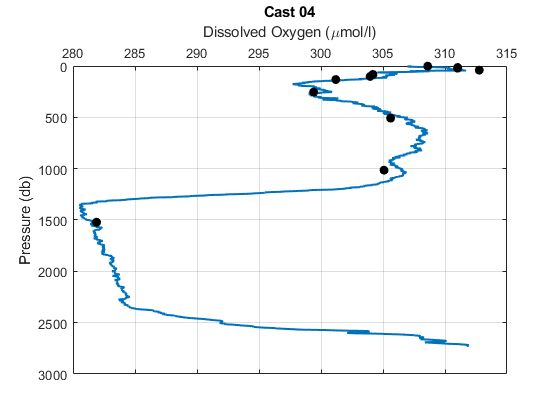


figure
plot(cast04.sbeox0mL_L*44.661,cast04.pm,'Linewidth',1.5)
hold on
plot(btlsum04.Winkler_mLL*44.661,btlsum04.PrDM,'ok','MarkerFaceColor','k')
axis ij
ax = gca;
ax.XAxisLocation = 'top';
xlabel('Dissolved Oxygen (\mumol/l)'); ylabel('Pressure (db)')
grid on
title('Cast 04')

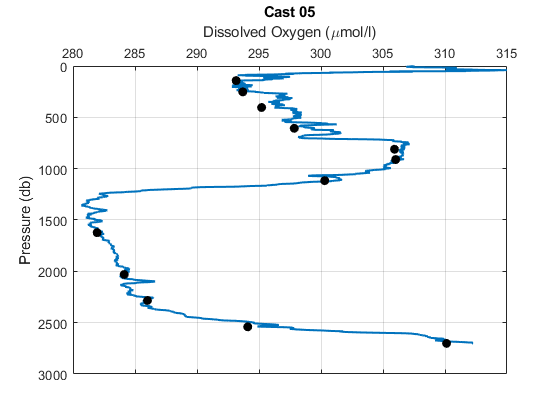


figure
plot(cast05.sbeox0mL_L*44.661,cast05.pm,'Linewidth',1.5)
hold on
plot(btlsum05.Winkler_mLL*44.661,btlsum05.PrDM,'ok','MarkerFaceColor','k')
axis ij
ax = gca;
ax.XAxisLocation = 'top';
xlabel('Dissolved Oxygen (\mumol/l)'); ylabel('Pressure (db)')
grid on
title('Cast 05')

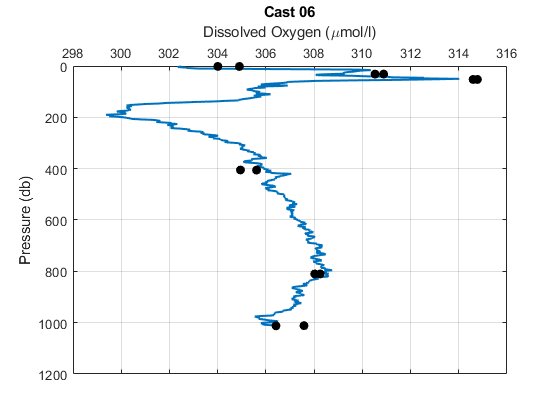


figure
plot(cast06.sbeox0mL_L*44.661,cast06.pm,'Linewidth',1.5)
hold on
plot(btlsum06.Winkler_mLL*44.661,btlsum06.PrDM,'ok','MarkerFaceColor','k')
axis ij
ax = gca;
ax.XAxisLocation = 'top';
xlabel('Dissolved Oxygen (\mumol/l)'); ylabel('Pressure (db)')
grid on
title('Cast 06')

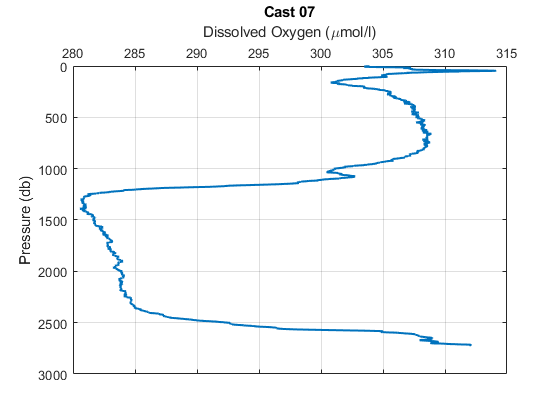


figure
plot(cast07.sbeox0mL_L*44.661,cast07.pm,'Linewidth',1.5)
axis ij
ax = gca;
ax.XAxisLocation = 'top';
xlabel('Dissolved Oxygen (\mumol/l)'); ylabel('Pressure (db)')
grid on
title('Cast 07')

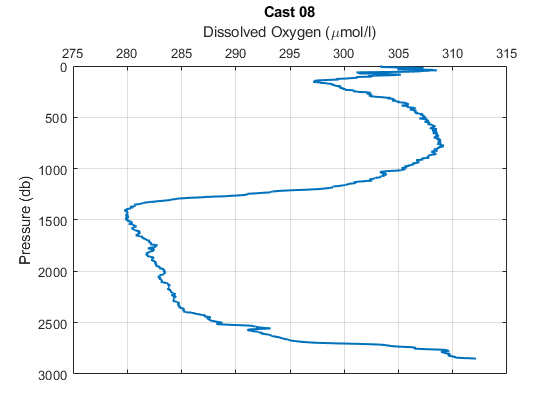


figure
plot(cast08.sbeox0mL_L*44.661,cast08.pm,'Linewidth',1.5)
axis ij
ax = gca;
ax.XAxisLocation = 'top';
xlabel('Dissolved Oxygen (\mumol/l)'); ylabel('Pressure (db)')
grid on
title('Cast 08')

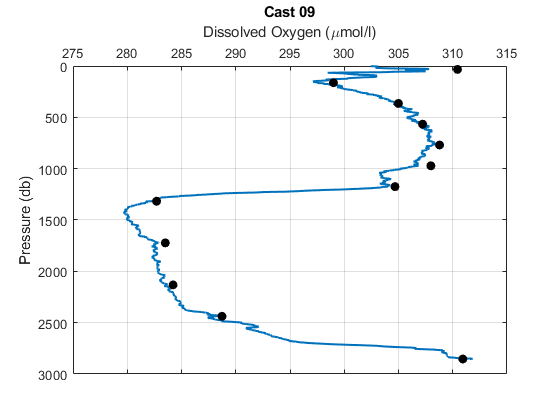


figure
plot(cast09.sbeox0mL_L*44.661,cast09.pm,'Linewidth',1.5)
hold on
plot(btlsum09.Winkler_mLL*44.661,btlsum09.PrDM,'ok','MarkerFaceColor','k')
axis ij
ax = gca;
ax.XAxisLocation = 'top';
xlabel('Dissolved Oxygen (\mumol/l)'); ylabel('Pressure (db)')
grid on
title('Cast 09')

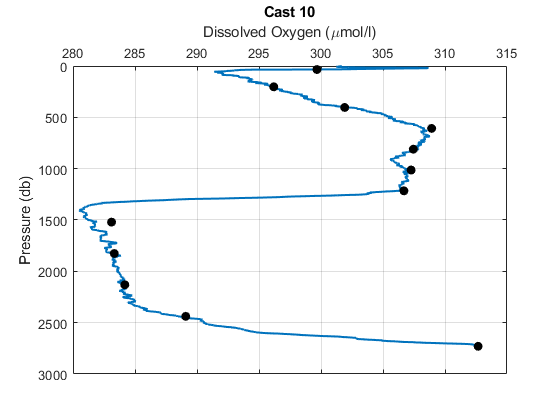


figure
plot(cast10.sbeox0mL_L*44.661,cast10.pm,'Linewidth',1.5)
hold on
plot(btlsum10.Winkler_mLL*44.661,btlsum10.PrDM,'ok','MarkerFaceColor','k')
axis ij
ax = gca;
ax.XAxisLocation = 'top';
xlabel('Dissolved Oxygen (\mumol/l)'); ylabel('Pressure (db)')
grid on
title('Cast 10')

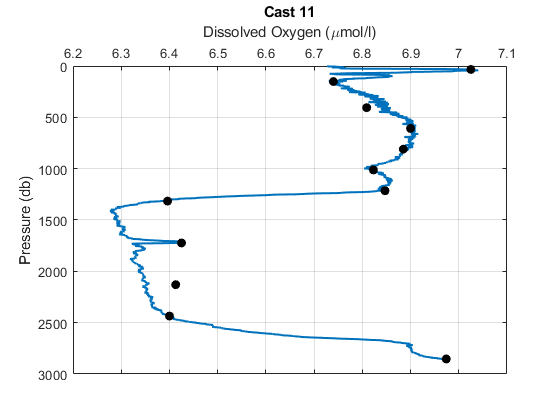


figure
plot(cast11.sbeox0mL_L,cast11.pm,'Linewidth',1.5)
hold on
plot(btlsum11.Winkler_mLL,btlsum11.PrDM,'ok','MarkerFaceColor','k')
axis ij
ax = gca;
ax.XAxisLocation = 'top';
xlabel('Dissolved Oxygen (\mumol/l)'); ylabel('Pressure (db)')
grid on
title('Cast 11')

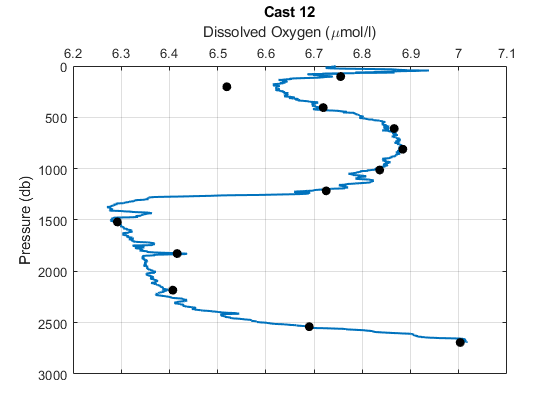


figure
plot(cast12.sbeox0mL_L,cast12.pm,'Linewidth',1.5)
hold on
plot(btlsum12.Winkler_mLL,btlsum12.PrDM,'ok','MarkerFaceColor','k')
axis ij
ax = gca;
ax.XAxisLocation = 'top';
xlabel('Dissolved Oxygen (\mumol/l)'); ylabel('Pressure (db)')
grid on
title('Cast 12')

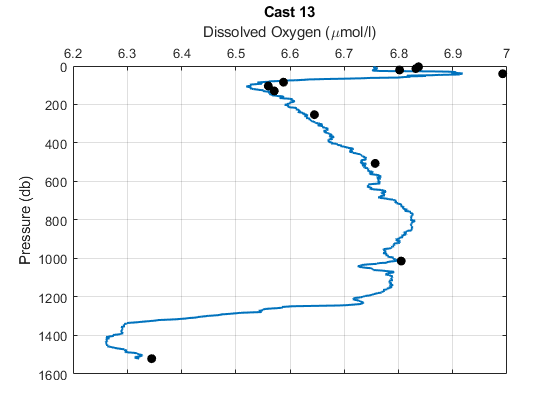


figure
plot(cast13.sbeox0mL_L,cast13.pm,'Linewidth',1.5)
hold on
plot(btlsum13.Winkler_mLL,btlsum13.PrDM,'ok','MarkerFaceColor','k')
axis ij
ax = gca;
ax.XAxisLocation = 'top';
xlabel('Dissolved Oxygen (\mumol/l)'); ylabel('Pressure (db)')
grid on
title('Cast 13')